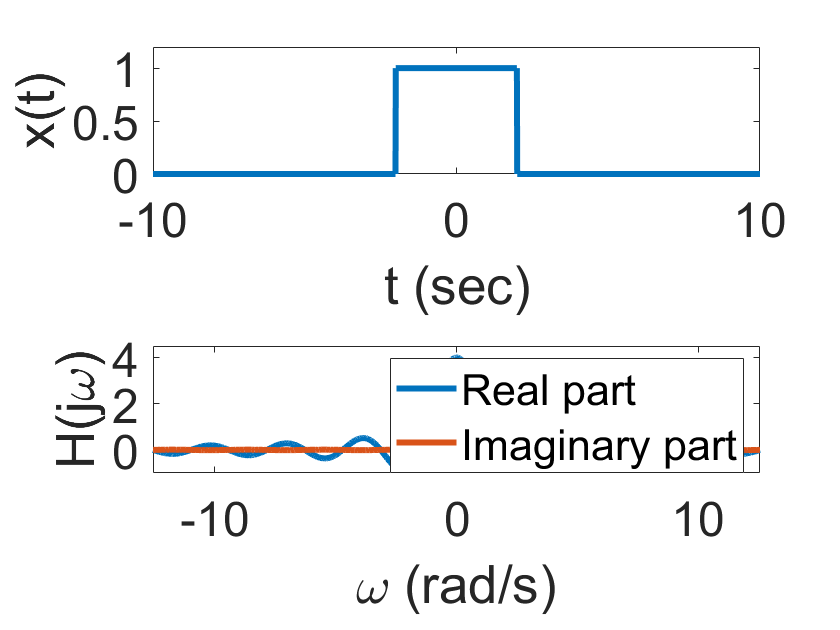

% Plotting the spectrum of a rectangular pulse
t=-10:.01:10;
w=-4*pi:.01:4*pi;
x=rectpuls(t/4);
X=ctft(t,x,w);
subplot(2,1,1)
plot(t,x,'linewidth',3);
set(gca,'fontsize',24)
axis([-10 10 0 1.2])
xlabel('t (sec)')
ylabel('x(t)')
subplot(2,1,2)
plot(w,real(X),'linewidth',3);
hold on
plot(w,imag(X),'linewidth',3);
set(gca,'fontsize',24)
legend('Real part','Imaginary part')
axis([min(w) max(w) -1 4.5])
xlabel('\omega (rad/s)')
ylabel('H(j\omega)')